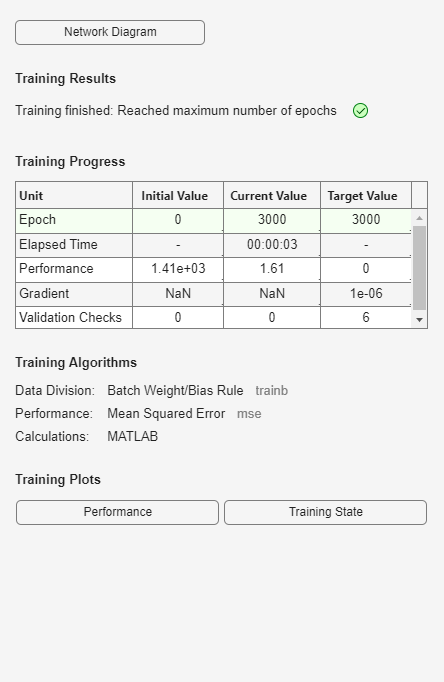

%ÏßÐÔÍøÂç¡ª¡ªµ¥ÊäÈë-µ¥Êä³ö£¨yÖµÁ¿¸Ù²»¸Ä±ä£©
x=[15.2 10.4 21.2 18.6 26.4 23.4 13.5 16.7 24.0 19.1]; 
y=[28.6 19.3 40.5 35.6 48.9 45.0 29.2 34.1 46.7 37.4];
P=x/10;                                     %ÊäÈëÊý¾ÝÈ«²¿³ýÒÔ10
T=y;                                        %Ä¿±êÊý¾Ý²»¸Ä±ä
net=newlin(minmax(P),1,0,0.01);             %¹¹½¨Ò»¸öµ¥Êä³öÏßÐÔÍøÂç
net.trainParam.epochs=3000;                 %Ö¸¶¨×î´ó¼ÆËã´ÎÊý
net=train(net,P,T);                         %ÍøÂçÑµÁ·

Y=sim(net,P);Y                              %·ÂÕæÓëÊýÖµÊä³ö

Y =    29.9128   21.2108   40.7904   36.0768   50.2176   44.7788   26.8309   32.6322   45.8665   36.9832


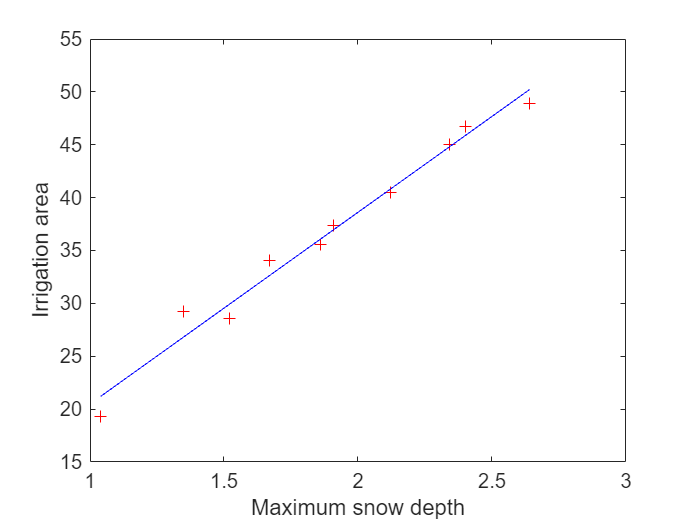

figure                                      %´´½¨ÁíÍâÒ»¸öÍ¼ÐÎ´°¿Ú
plot(P,T,'r+');                             %»æÖÆÉ¢µãÍ¼
xlabel('Maximum snow depth');               %ºáÖá±êÇ©£¨×î´ó»ýÑ©Éî¶È£©
ylabel('Irrigation area');                  %×ÝÖá±êÇ©£¨¹à¸ÈÃæ»ý£©
hold on                                     %±£³ÖÍ¼ÐÎ
plot(P,Y,'b-');                             %Ìí¼ÓÇ÷ÊÆÏß
hold off                                    %½áÊø»æÍ¼

w=net.iw{1,1}                               %¸ø³öÈ¨Êý/»Ø¹éÏµÊý

w = 18.1292

b=net.b{1}                                  %¸ø³öãÐÖµ/½Ø¾à

b = 2.3564

P_test=[27.5/10];                           %Ô¤²â
y=sim(net,P_test);                          %¼ÆËãÔ¤²â½á¹û
Y1981=y                                     %½«Ô¤²âÖµ×ª»»ÎªÔ­À´µÄÊýÖµµ¥Î»

Y1981 = 52.2118